clear all
close all
c=ConstantObj();  % all the constants, we suggest to use c.g rather than 9.81 in the script to enhance readerbility;

fprintf('%s The current working directory is %s \n',date, pwd)

16-Jun-2022 The current working directory is Z:\home\Student\s4680073\macondo\test\dual_porosity\20220616_test_swcc\case1a 


fprintf('Now Producing SUTRA input files \n',pwd)

Now Producing SUTRA input files 


%% SUTRA.fil

fil=filObj('read_from_file','no');

% the default value for 'fid' is -1, meaning, this will not write to SUTRA.fil if export
fil.terms.('inp').('fname')        = 'PART1.inp' ; fil.terms.('inp').('fid')   = 50;
fil.terms.('ics').('fname')        = 'PART1.ics' ; fil.terms.('ics').('fid')   = 55;
fil.terms.('lst').('fname')        = 'PART1.lst' ; fil.terms.('lst').('fid')   = 60;
fil.terms.('rst').('fname')        = 'PART1.rst' ; fil.terms.('rst').('fid')   = 66;
fil.terms.('nod').('fname')        = 'PART1.nod' ; fil.terms.('nod').('fid')   = 30;
fil.terms.('ele').('fname')        = 'PART1.ele' ; fil.terms.('ele').('fid')   = 40;
fil.terms.('obs').('fname')        = 'PART1.obs' ; fil.terms.('obs').('fid')   = 70;
fil.terms.('smy').('fname')        = 'PART1.smy' ; fil.terms.('smy').('fid')   = 80;
fil.terms.('bcof').('fname')       = 'PART1.bcof'; fil.terms.('bcof').('fid')  = 91;
fil.terms.('bcos').('fname')       = 'PART1.bcos'; fil.terms.('bcos').('fid')  = 93;
fil.terms.('bcop').('fname')       = 'PART1.bcop'; fil.terms.('bcop').('fid')  = 92;
fil.terms.('bcou').('fname')       = 'PART1.bcou'; fil.terms.('bcou').('fid')  = 94;
fil.terms.('bcs').('fname')        = 'PART1.bcs' ; fil.terms.('bcs').('fid')   = 96;


fil.export_to_file();

Writting to file SUTRA.FIL


fil.export_to_file();

Writting to file SUTRA.FIL


c_saltwater_kgPkg                  = 0.035;
c_freshwater_kgPkg                 = 0.001;
initial_head_aquifer_m             = -3;
initial_pond_water_depth_m         = 0.5; % unused 
initial_silt_layer_pressure_pa     = -5e4 % CZ220616 a mark here as the corresponding moiture content to this pressure could be very high.

initial_silt_layer_pressure_pa = -50000

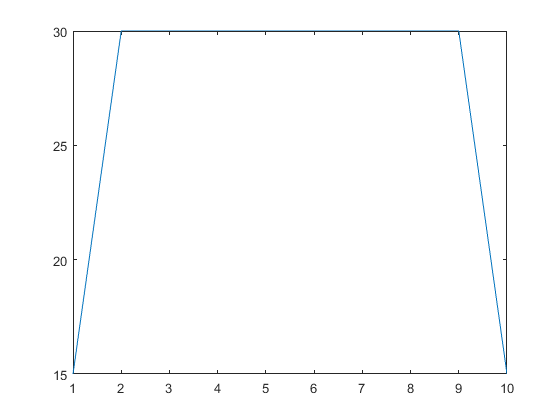

permeability_silt_m2               = 1e-15;      % bulk coonambidgal clay 
permeability_silt_high_m2          = 7.38e-15;   % unused
permeability_macropore_m2          = 1e-14;
permeability_aquitard_m2           = 1e-17;
% permeability_macropore_to_matrix = 
permeability_sand_m2               = 3e-12;
permeability_pond_m2               = 5.38e-8;
pond_radius_m                      = 120.1;
pond_depth_m                       = -1.0;   % z_coordinate_pond_bottom_m
porosity_sand                      = 0.1;
porosity_silt                      = 0.2;
% porosity_silt_below_pond         = 0.8;
porosity_pond                      = 0.5;
porosity_macropore                 = 0.03;
pi                                 = 3.1416;
silt_below_pond_thickness_m        = 1;  % CZ220616 unused 
depth_groundwater_table_m          = -7;  
thickness_aquitard_m               = 1.0;
%% inp file
dx                                 = 30;
dz                                 = -1;
x_array                            = 1 : dx : 300;
z_array                            = 1 : dz : -10;
nx                                 = length(x_array);
nz                                 = length(z_array);
ny                                 = 3; %%number of layer (z). In this case equals 2 indicating 2 layers: matrix and pore space;
nex                                = length(x_array)-1;
nez                                = length(z_array)-1;
ney                                = ny-1;

%%
[x_nod_mtx_2d,z_nod_mtx_2d]        = meshgrid( x_array , z_array );
y_nod_mcpore_mtx_2d                = -2. * pi * x_nod_mtx_2d;
y_nod_matrix_mtx_2d                =  2. * pi * x_nod_mtx_2d;
y_nod_mid_mtx_2d                   = zeros( size ( x_nod_mtx_2d ) );

x_nod_mtx_3d = cat( 3 , x_nod_mtx_2d , x_nod_mtx_2d , x_nod_mtx_2d);
y_nod_mtx_3d = cat( 3 , y_nod_mcpore_mtx_2d , y_nod_mid_mtx_2d , y_nod_matrix_mtx_2d);
z_nod_mtx_3d = cat( 3 , z_nod_mtx_2d        ,      z_nod_mtx_2d, z_nod_mtx_2d);

x_nod_mtx_3d = permute(x_nod_mtx_3d,[1 3 2]);  % CZ220616 suggest to change this variable to x_nod_mtx_3d_zyx_m
y_nod_mtx_3d = permute(y_nod_mtx_3d,[1 3 2]);
z_nod_mtx_3d = permute(z_nod_mtx_3d,[1 3 2]);


% cz220616 unclear
keynodes                           = zeros ( size(x_nod_mtx_3d,1) , size(x_nod_mtx_3d,2) , size(x_nod_mtx_3d,3) + 1);
keynodes( : , : , 2 : end-1)       = ( x_nod_mtx_3d ( : , : , 1 : end - 1) + x_nod_mtx_3d( : , : , 2 : end) ) / 2;
keynodes( : , : , 1)               = x_nod_mtx_3d ( : , : , 1);
keynodes(:,:,end)                  = x_nod_mtx_3d( : , : , end);
dx_cell_mtx_3d                     = diff(keynodes,1,3); % check inbuilding function diff

keynodes                           = zeros(size(z_nod_mtx_3d,1)+1,size(z_nod_mtx_3d,2),size(z_nod_mtx_3d,3) );
keynodes(2:end-1,:,:)              = (z_nod_mtx_3d(1:end-1,:,:)+z_nod_mtx_3d(2:end,:,:) )/2;
keynodes(1,:,:)                    = z_nod_mtx_3d(1,:,:);
keynodes(end,:,:)                  = z_nod_mtx_3d(end,:,:);
dz_cell_mtx_3d                     = diff(keynodes,1,1); % check inbuilding function diff
% keynodes                         = zeros(size(y_nod_mtx,1)+1,size(y_nod_mtx,2));
% keynodes(2:end-1,:)              = (y_nod_mtx(1:end-1,:)+y_nod_mtx(2:end,:))/2;
% keynodes(1,:)                    = y_nod_mtx(1,:);
% keynodes(end,:)                  = y_nod_mtx(end,:);
% dy_cell_mtx                      = diff(keynodes,1,1); % check inbuilding function diff
% dy_cell_mtx_gravity_compensated  = flipud(dy_cell_mtx);

nn                                 = nx * ny * nz;
ne                                 = (nx-1)*(ny-1)*(nz-1);
sequence                           = 'zyx';
%dataset 14
ii                                 = (1:nn)';
x_nod_array                        = x_nod_mtx_3d(:);
y_nod_array                        = y_nod_mtx_3d(:);
z_nod_array                        = z_nod_mtx_3d(:);
node_index_mtx                     = reshape(ii,nz,ny,nx);  %note node_index_mtx(52) = 52
% node_index_mtx_gravity_compensated                                                                       = flip(node_index_mtx);   % this makes a matrix that maps the node position in a xy plane.
% x_nod_mtx_gravity_compensated_m  = flip(x_nod_mtx_3d);
% y_nod_mtx_gravity_compensated_m  = flip(y_nod_mtx_3d);
% z_nod_mtx_gravity_compensated_m  = flip(z_nod_mtx_3d);
% dx_cell_mtx_gravity_compensated_3d                                                                       = flip(dx_cell_mtx_3d);
% dx_cell_mtx_gravity_compensated_3d                                                                       = flip(dx_cell_mtx_3d);
dy_cell_mtx_3d                     = 2 .* pi * x_nod_mtx_3d; 
area_xy_nod_mtx_m2_2d(1,:)         = (1/4)*pi*(2*x_array+squeeze(dx_cell_mtx_3d(1,1,:) )') .* squeeze(dx_cell_mtx_3d(1,1,:) )';
area_xy_nod_mtx_m2_2d(2,:)         = 2*area_xy_nod_mtx_m2_2d(1,:);
area_xy_nod_mtx_m2_2d(3,:)         = area_xy_nod_mtx_m2_2d(1,:);
for i=1:nz
    area_xy_nod_mtx_m2_3d(i,:,:)   = area_xy_nod_mtx_m2_2d;
end
idx                                = 1;
iin1                               = zeros(ne,1);
iin2                               = zeros(ne,1);
iin3                               = zeros(ne,1);
iin4                               = zeros(ne,1);
iin5                               = zeros(ne,1);
iin6                               = zeros(ne,1);
iin7                               = zeros(ne,1);
iin8                               = zeros(ne,1);

x_ele_array                        = zeros(ne,1);
y_ele_array                        = zeros(ne,1);
z_ele_array                        = zeros(ne,1);

for k=1:nex
    for j                          = 1:ney
        for i                      = 1:nez
            iin1(idx)              = node_index_mtx(i+1,j,k);
            iin2(idx)              = node_index_mtx(i+1,j,k+1);
            iin3(idx)              = node_index_mtx(i+1,j+1,k+1);
            iin4(idx)              = node_index_mtx(i+1,j+1,k);
            iin5(idx)              = node_index_mtx(i,j,k);
            iin6(idx)              = node_index_mtx(i,j,k+1);
            iin7(idx)              = node_index_mtx(i,j+1,k+1);
            iin8(idx)              = node_index_mtx(i,j+1,k);       
            x_ele_array(idx)       = mean([x_nod_array(iin1(idx) ),x_nod_array(iin2(idx) ),x_nod_array(iin3(idx) ),x_nod_array(iin4(idx) ),...
																													x_nod_array(iin5(idx) ),x_nod_array(iin6(idx) ),x_nod_array(iin7(idx) ),x_nod_array(iin8(idx) )] )   ;  % use mean method to get the middle of the cell
            y_ele_array(idx)       = mean([y_nod_array(iin1(idx) ),y_nod_array(iin2(idx) ),y_nod_array(iin3(idx) ),y_nod_array(iin4(idx) ),...
																													y_nod_array(iin5(idx) ),y_nod_array(iin6(idx) ),y_nod_array(iin7(idx) ),y_nod_array(iin8(idx) )] )   ;  % use mean method to get the middle of the cell
            z_ele_array(idx)       = mean([z_nod_array(iin1(idx) ),z_nod_array(iin2(idx) ),z_nod_array(iin3(idx) ),z_nod_array(iin4(idx) ),...
																													z_nod_array(iin5(idx) ),z_nod_array(iin6(idx) ),z_nod_array(iin7(idx) ),z_nod_array(iin8(idx) )] )   ;  % use mean method to get the middle of the cell
            idx                    = idx + 1;
        end
    end
end

x_ele_mtx_3d                       = reshape(x_ele_array, nez,ney,nex);
y_ele_mtx_3d                       = reshape(y_ele_array, nez,ney,nex);
z_ele_mtx_3d                       = reshape(z_ele_array, nez,ney,nex);
plot(squeeze(dx_cell_mtx_3d(1,1,:) ) );           

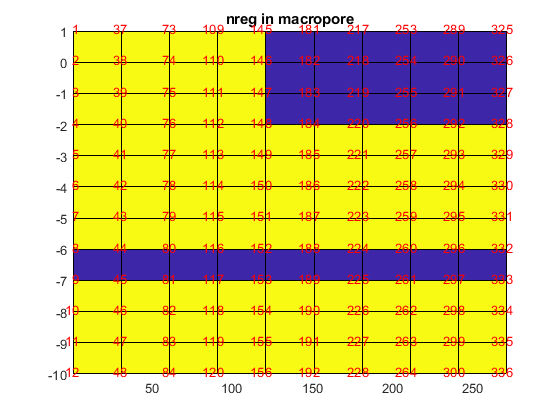

%%
% x_ele_mtx_gravity_compensated_m  = flip(x_ele_mtx_3d);
% y_ele_mtx_gravity_compensated_m  = flip(y_ele_mtx_3d);
% z_ele_mtx_gravity_compensated_m  = flip(z_ele_mtx_3d);

inp                                = inpObj('PART1','read_from_file','no');   % setup a empty inpObj
% dataset 1
inp.title1                         = 'E-watering project';
inp.title2                         = 'Generating input using sutralab';
% dataset 2a
%'SUTRA VERSION 2.2 SOLUTE TRANSPORT'
%'3D REGULAR MESH'
inp.vermin                         = '2.2';  % note this should be a string not a number;
inp.simula                         = 'SOLUTE';
% dataset 2b
 %        2d mesh   ==>   ktype(1) = 2
 %        3d mesh   ==>   ktype(1) = 3
 %        irregular mesh                                                                    ==>   ktype(2) = 0
 %        layered mesh                                                                      ==>   ktype(2) = 1
 %        regular mesh                                                                      ==>   ktype(2) = 2
 %        blockwise mesh                                                                    ==>   ktype(2) = 3

inp.ktype(1)                       = 3;  % 3D mesh
inp.mshtyp{1}                      = '3D';
inp.mshtyp{2}                      = 'REGULAR';

inp.nn1                            = nz;
inp.nn2                            = ny;
inp.nn3                            = nx;
% ##  DATASET 3:  Simulation Control Numbers
inp.nn                             = nn;
inp.ne                             = ne;
inp.npbc                           = 0;   %length(ipbc);  revised after dataset 19
inp.nubc                           = 0;
% inp.nsop                         = 4;       % dataset 17
inp.nsou                           = 0;
inp.nobs                           = 0;

%%##  DATASET 4:  Simulation Mode Options

inp.cunsat                         = 'UNSATURATED';
inp.cssflo                         = 'TRANSIENT FLOW';
inp.csstra                         = 'TRANSIENT TRANSPORT';
inp.cread                          = 'COLD' ;
inp.istore                         = 9999;

%%##  DATASET 5:  Numerical Control Parameters
inp.up                             = 0;
inp.gnup                           = 1e-2;
inp.gnuu                           = 0.01;

%  DATASET 6:  Temporal Control and Solution Cycling Data
%  
inp.nsch                           = 2;
inp.npcyc                          = 1;
inp.nucyc                          = 72000000;
    
%DATASET 6:  Temporal Control and Solution Cycling Data

inp.schnam                         = 'TIME_STEPS';
inp.schtyp                         = 'TIME CYCLE';
inp.creft                          = 'ELAPSED';
%inp.scalt                         = 6000;   %reduce to 3000
%inp.scalt                         = 3000;   %reduce to 3000
%inp.scalt                         = 600;   %reduce to 3000
inp.scalt                          = 100;   %reduce to 3000
%inp.scalt                         = 50;   %reduce to 3000
%inp.scalt                         = 6000;   %reduce to 3000
%inp.scalt                         = 0.6;   %reduce to 3000
% inp.ntmax                        = 20000;
inp.ntmax                          = 3*20000*(600/inp.scalt);
inp.timei                          = 0;
inp.timel                          = 1.e99;
inp.timec                          = 1.;
inp.ntcyc                          = 9999;
inp.tcmult                         = 1;
inp.tcmin                          = 1.e-20;
inp.tcmax                          = 1.e99;

% add the send schedule to control water inflow
inp.schnam_2                       = 'Timed_Obs'	;
inp.schtyp_2                       = 'STEP LIST'	;
inp.nslist_2                       = 8;
%inp.islist_2                      = [1  4320  8000     9000 ];
%inp.islist_2                      = [1  1152  10800     11232 ];
%inp.islist_2                      = [1  1152  10800     11232 ];
inp.islist_2                       = floor([inp.scalt  800000    0.94*6480000    0.94*6609600 9740500 14924500 309*86400 316.9*86400]/inp.scalt);   % CZ210915 to allow bcs to adjust with time steps,consider the effect of rainfall

%'Timed_Obs'	    'STEP LIST'	    4 1  4320  8000     9000  

%##  DATASET 7:  ITERATION AND MATRIX SOLVER CONTROLS
%##  [ITRMAX]        [RPMAX]        [RUMAX]
inp.itrmax                         = 1000;
inp.rpmax                          = 1e+5;
%inp.rpmax                         = 5e-2;  TO200317 too strigent for the first step
inp.rumax                          = 1.0e-1;
% ##  [CSOLVP]  [ITRMXP]         [TOLP]
inp.csolvp                         = 'ORTHOMIN' ;
inp.itrmxp                         = 3000;
inp.tolp                           = 1e-12;

%##  [CSOLVU]  [ITRMXU]         [TOLU]
inp.csolvu                         = 'ORTHOMIN';
inp.itrmxu                         = 3000;
inp.tolu                           = 1e-12;

%##  DATASET 8:  Output Controls and Options
%## [NPRINT]  [CNODAL]  [CELMNT]  [CINCID]  [CPANDS]  [CVEL]  [CCORT] [CBUDG]   [CSCRN]  [CPAUSE]
%   2920        'N'        'N'        'N'        'Y'     'Y'        'Y'    'Y'      'Y' 'Y' 'Data Set 8A'

inp.nprint                         = 1000;
inp.cnodal                         = 'Y';
inp.celmnt                         = 'Y';
inp.cincid                         = 'N';
inp.cpands                         = 'Y';
inp.cvel                           = 'Y';
inp.ccort                          = 'N';
inp.cbudg                          = 'Y';
inp.cscrn                          = 'N';   % screen output
inp.cpause                         = 'Y';

inp.ncolpr                         = -100;
%inp.ncol                          = 'N'  'X'  'Y'  'Z'  'P'  'U'  'S'  '-';
inp.ncol                           = {['N'],['X' ],[ 'Y'  ],[ 'Z'  ],['P' ],[ 'U' ],[ 'S' ],[ '-']};

inp.lcolpr                         = 100;
inp.lcol                           = {[ 'E' ],[ 'X' ],[ 'Y'  ],[ 'Z'  ],['VX' ],['VY' ],['VZ' ],['-']};

inp.nbcfpr                         = 100;
inp.nbcspr                         = 100;
inp.nbcppr                         = 100;
inp.nbcupr                         = 100;
inp.cinact                         = 'Y';



%##    DATASET 9:  FLUID PROPERTIES
inp.compfl                         = 1.e-11;
inp.cw                             = 1.;
inp.sigmaw                         = 1.e-8;
inp.rhow0                          = 1000;
inp.urhow0                         = 0;
inp.drwdu                          = 700;
inp.visc0                          = 0.001;


%##      DATASET 10:  SOLID MATRIX PROPERTIES
inp.compma                         = 1.e-6;
inp.cs                             = 0;
inp.sigmas                         = 0;
inp.rhos                           = 2600;   %solid density of sodium chloride

%##  DATASET 11:  Adsorption Parameters
%##     [ADSMOD]         [CHI1]         [CHI2]
%#'NONE'
%'FREUNDLICH' 1.D-47 0.05  #less rigid

%inp.adsmod                        = 'FREUNDLICH';
inp.adsmod                         = 'NONE';
inp.chi1                           = 1.D-46;
inp.chi2                           = 0.05 ;

%##
%##  DATASET 12:  Production of Energy or Solute Mass
%##     [PRODF0]       [PRODS0]       [PRODF1]       [PRODS1]
%0.             0.             0.             0.
inp.prodf0                         = 0;
inp.prods0                         = 0;
inp.prodf1                         = 0;
inp.prods1                         = 0;


%##
%##  DATASET 13:  Orientation of Coordinates to Gravity
%##      [GRAVX]        [GRAVY]        [GRAVZ]
%0.           -9.81          0.
inp.gravx                          = 0;
inp.gravy                          = 0;
inp.gravz                          = -9.81;

%##  DATASET 14:  NODEWISE DATA
%%##                              [SCALX] [SCALY] [SCALZ] [PORFAC]
inp.scalx                          = 1.;
inp.scaly                          = 1.;
inp.scalz                          = 1.;
inp.porfac                         = 1.;

%##      [II]    [NRE    G(II)]  [X(II)] [Y(II)] [Z(II)] [POR(II)]
mask_nod_mtx_pond_cell             = and(z_nod_mtx_3d >= pond_depth_m, x_nod_mtx_3d < pond_radius_m);
mask_nod_mtx_macropore             = and(depth_groundwater_table_m+1 < z_nod_mtx_3d & z_nod_mtx_3d < pond_depth_m,y_nod_mtx_3d < 0);
mask_nod_mtx_sand_layer            = z_nod_mtx_3d  <= depth_groundwater_table_m  ;   % mask matrix, for nod matrix 
% mask_nod_mtx_middle_and_clay             =and(depth_groundwater_table_m<z_nod_mtx_3d & z_nod_mtx_3d<pond_depth_m,y_nod_mtx_3d>);
nreg                               = zeros(size(x_nod_mtx_3d))+1;
nreg(mask_nod_mtx_macropore)       = 7; 
nreg(mask_nod_mtx_pond_cell)       = 7; 
nreg(mask_nod_mtx_sand_layer)      = 7; 
pcolor(x_nod_mtx_2d,z_nod_mtx_2d,squeeze(nreg(:,1,:) ) );
node_index_pore_mtx                = node_index_mtx(:,1,:);
node_index_matrix_array            = node_index_pore_mtx(:);
text(x_nod_mtx_2d(:)+0.15*dx,z_nod_mtx_2d(:)-0.2,string(node_index_matrix_array),'VerticalAlignment','bottom','HorizontalAlignment','right','color','r');
title('nreg in macropore');

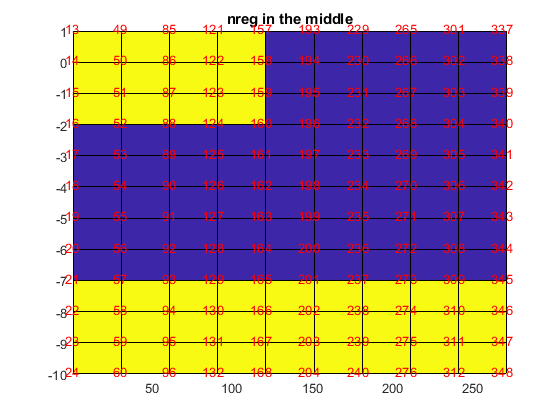


%%
pcolor(x_nod_mtx_2d,z_nod_mtx_2d,squeeze(nreg(:,2,:) ) );
node_index_matrix_mtx              = node_index_mtx(:,2,:);
node_index_matrix_array            = node_index_matrix_mtx(:);
text(x_nod_mtx_2d(:)+0.15*dx,z_nod_mtx_2d(:)-0.2,string(node_index_matrix_array),'VerticalAlignment','bottom','HorizontalAlignment','right','color','r');
title('nreg in the middle')

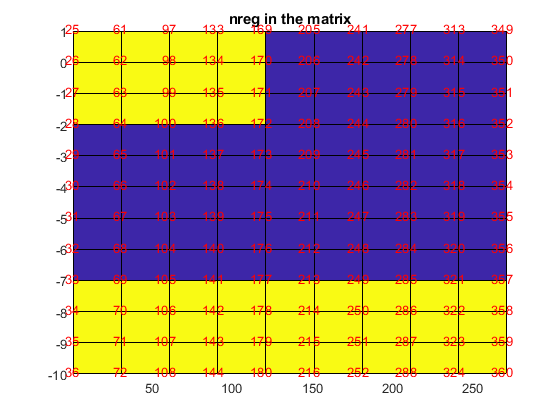

%%
pcolor(x_nod_mtx_2d,z_nod_mtx_2d,squeeze(nreg(:,3,:) ) );
node_index_matrix_mtx              = node_index_mtx(:,3,:);
node_index_matrix_array            = node_index_matrix_mtx(:);
text(x_nod_mtx_2d(:)+0.15*dx,z_nod_mtx_2d(:)-0.2,string(node_index_matrix_array),'VerticalAlignment','bottom','HorizontalAlignment','right','color','r');
title('nreg in the matrix')

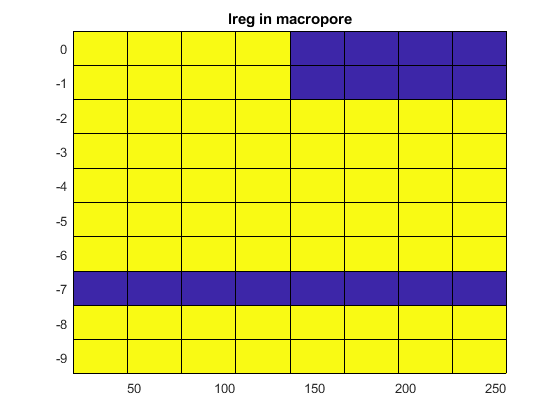

%%
inp.ii                             = (1:nn)';
inp.nreg                           = nreg(:);
inp.x                              = x_nod_array;
inp.y                              = y_nod_array;
%inp.z                             = zeros(nn,1)+dz;
inp.z                              = z_nod_array;
%%

%##                              [PMAXFA]        [PMINFA]        [ANG1FA]        [ALMAXF]        [ALMINF]        [ATMAXF]        [ATMINF]
%'ELEMENT'               1.0000000D+00   1.0000000D+00   1.0000000D+00   2 2 2 2
%##     [L]      [LREG(L)]       [PMAX(L)]       [PMIN(L)]       [ANGLEX(L)]     [ALMAX(L)]      [ALMIN(L)]      [ATMAX(L)]      [ATMIN(L)]
mask_ele_mtx_silt_layer            = z_ele_mtx_3d  > depth_groundwater_table_m   ;   % mask matrix, for element matrix 
mask_ele_mtx_sand_layer            = z_ele_mtx_3d  < depth_groundwater_table_m   ;   % mask matrix, for element matrix 
mask_ele_mtx_aquitard_layer        = and(z_ele_mtx_3d  > depth_groundwater_table_m,z_ele_mtx_3d  <= depth_groundwater_table_m +thickness_aquitard_m)  ;   % mask matrix, for element matrix 
mask_ele_mtx_macropore             = and(depth_groundwater_table_m+1 < z_ele_mtx_3d & z_ele_mtx_3d < pond_depth_m,y_ele_mtx_3d<0);
mask_ele_mtx_macropore_for_pmid    = and(depth_groundwater_table_m+1 < z_ele_mtx_3d , z_ele_mtx_3d < pond_depth_m);

mask_ele_mtx_silt_layer_below_pond = zeros(nez,ney,nex);
mask_ele_mtx_pond_layer            = and(z_ele_mtx_3d >= pond_depth_m, x_ele_mtx_3d < pond_radius_m);

lreg                               = zeros(size(x_ele_mtx_3d))+1;
lreg(mask_ele_mtx_macropore)       = 7; 
lreg(mask_ele_mtx_pond_layer)      = 7; 
lreg(mask_ele_mtx_sand_layer)      = 7; 
pcolor(squeeze(x_ele_mtx_3d(:,1,:) ),squeeze(z_ele_mtx_3d(:,1,:) ),squeeze(lreg(:,1,:) ) );
title('lreg in macropore');

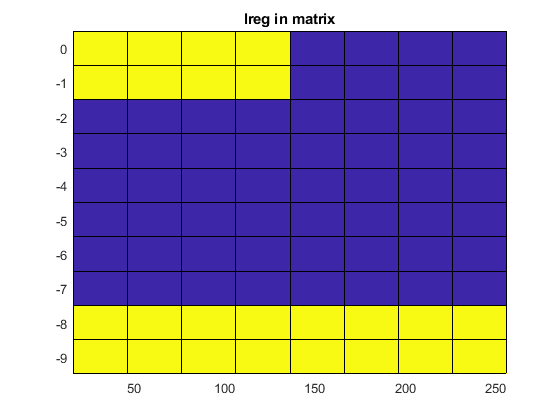

%%
pcolor(squeeze(x_ele_mtx_3d(:,2,:) ),squeeze(z_ele_mtx_3d(:,2,:) ),squeeze(lreg(:,2,:) ) );
title('lreg in matrix');

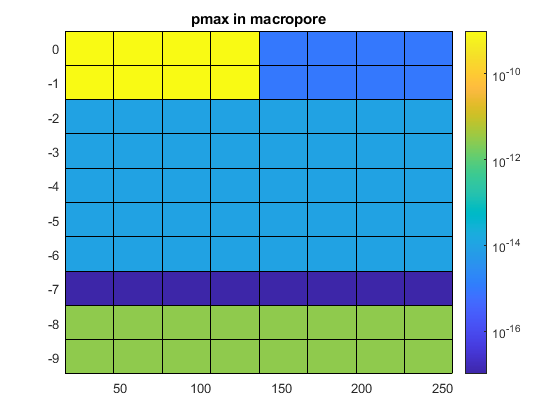

%%
inp.pmaxfa                         = 1.;
inp.pmidfa                         = 1.;
inp.pminfa                         = 1.;
inp.ang1fa                         = 1.;
inp.ang2fa                         = 1.;
inp.ang3fa                         = 1.;
inp.almaxf                         = 1.;
inp.almidf                         = 1.;
inp.alminf                         = 1.;
inp.atmaxf                         = 1.;
inp.atmidf                         = 1.;
inp.atminf                         = 1.;
inp.l                              = (1:ne)';
inp.lreg                           = lreg(:);

%%define the permeability of the matrix
pmax_mtx_m2                        = zeros(size(x_ele_mtx_3d) ) + permeability_sand_m2 ;   %background permeability
pmid_mtx_m2                        = zeros(size(x_ele_mtx_3d) ) + permeability_sand_m2 ;   %background permeability
mask_ele_mtx_silt_layer            = z_ele_mtx_3d  > depth_groundwater_table_m   ;   % mask matrix, for element matrix 
mask_ele_mtx_sand_layer            = z_ele_mtx_3d  <= depth_groundwater_table_m   ;   % mask matrix, for element matrix 

mask_ele_mtx_aquitard_layer        = and(z_ele_mtx_3d  > depth_groundwater_table_m,z_ele_mtx_3d  <= depth_groundwater_table_m +thickness_aquitard_m)  ;   % mask matrix, for element matrix 

pmax_mtx_m2 (mask_ele_mtx_silt_layer)                                                                      = permeability_silt_m2;   % silt layer permeability

mask_ele_mtx_pond_boundary         = zeros(size(mask_ele_mtx_silt_layer));
location_of_pond_boundary_ele      = zeros(nx-1,1);
index_location_of_pond_boundary_ele= zeros(nx-1,1);

[MY , IZ]                          = min(abs(z_ele_mtx_3d(:,1,1) - pond_depth_m));
[MX , IX]                          = min(abs(x_ele_mtx_3d(1,1,:) - pond_radius_m));

[M_high_permeability_silt_bottom , I_high_permeability_silt_bottom]                                        = min(abs(z_ele_mtx_3d(IZ,1,1)-z_ele_mtx_3d(:,1,1)-...
                                        silt_below_pond_thickness_m)) ;    
mask_ele_mtx_pond_boundary(IZ,:,1:IX)                                                                      = 1;
mask_ele_mtx_pond_boundary         = logical(mask_ele_mtx_pond_boundary);
location_of_pond_boundary_ele(1:IX)= y_ele_mtx_3d(IZ,1,1:IX);
index_location_of_pond_boundary_ele(1:IX)                                                                  = IZ;

mask_ele_mtx_silt_layer_below_pond(IZ+1:I_high_permeability_silt_bottom,:,1:IX)                            = 1;
mask_ele_mtx_silt_layer_below_pond=logical(mask_ele_mtx_silt_layer_below_pond);

% pmax_mtx_gravity_compensated_m2 (mask_ele_mtx_silt_layer_below_pond_gravity_compensatred)                =  permeability_silt_high_m2;   % pond  permeability
%%define the permeability of the marcropore. Only the layer below the pond
%%use the permealibity of the pore zone


pmax_mtx_m2 (mask_ele_mtx_pond_layer)                                                                      = permeability_pond_m2;   % pond  permeability
pmax_mtx_m2 (mask_ele_mtx_macropore)                                                                       = permeability_macropore_m2;   % pond  permeability
pmax_mtx_m2 (mask_ele_mtx_aquitard_layer)                                                                  = permeability_aquitard_m2;   % silt layer permeability
pcolor(squeeze(x_ele_mtx_3d(:,1,:) ),squeeze(z_ele_mtx_3d(:,1,:) ),squeeze(pmax_mtx_m2(:,1,:) ) );
set(gca,'ColorScale','log');
colorbar;caxis([1e-17 1e-9]);
title('pmax in macropore');

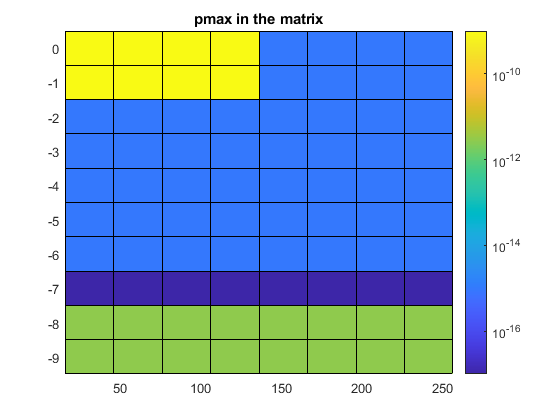

pcolor(squeeze(x_ele_mtx_3d(:,2,:) ),squeeze(z_ele_mtx_3d(:,2,:) ),squeeze(pmax_mtx_m2(:,2,:) ) );
set(gca,'ColorScale','log');
colorbar;caxis([1e-17 1e-9])
title('pmax in the matrix');

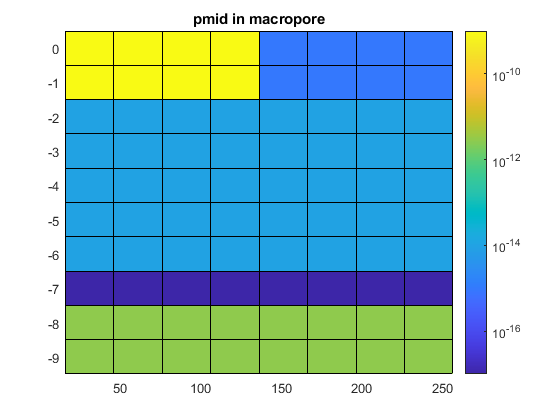

%%pmid is the permeability in the direction across marcopore and matrix
pmid_mtx_m2                        = pmax_mtx_m2;   % pond  permeability
pmax_mtx_m2                        = pmax_mtx_m2;
pmax_array_m2                      = pmax_mtx_m2(:);
pmid_mtx_m2(mask_ele_mtx_macropore_for_pmid)                                                               = permeability_macropore_m2;
pmid_array_m2                      = pmid_mtx_m2(:);

%%
pcolor(squeeze(x_ele_mtx_3d(:,1,:) ),squeeze(z_ele_mtx_3d(:,1,:) ),squeeze(pmid_mtx_m2(:,1,:) ) );
set(gca,'ColorScale','log');
colorbar;caxis([1e-17 1e-9])
title('pmid in macropore');

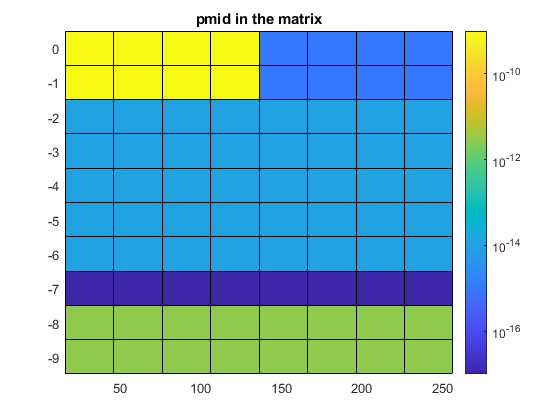

pcolor(squeeze(x_ele_mtx_3d(:,2,:) ),squeeze(z_ele_mtx_3d(:,2,:) ),squeeze(pmid_mtx_m2(:,2,:) ) );
set(gca,'ColorScale','log');
colorbar;caxis([1e-17 1e-9])
title('pmid in the matrix');

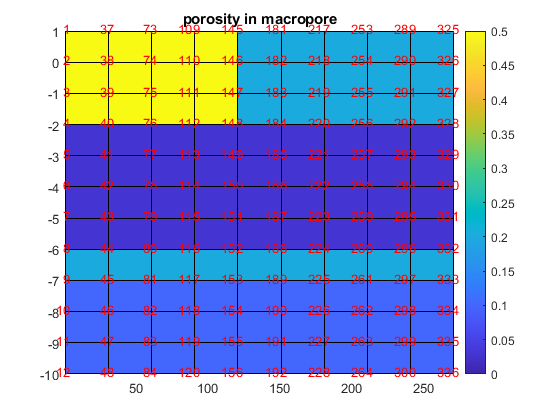

%%


inp.pmax                           = pmax_array_m2;
inp.pmid                           = pmid_array_m2;
inp.pmin                           = pmax_array_m2;
inp.angle1                         = zeros(ne,1);
inp.angle2                         = zeros(ne,1);
inp.angle3                         = zeros(ne,1);
inp.almax                          = zeros(ne,1)+1e-0;
inp.almid                          = zeros(ne,1)+1e-0;
inp.almin                          = zeros(ne,1)+1e-0;
inp.atmax                          = zeros(ne,1)+0.5e-0;
inp.atmid                          = zeros(ne,1)+0.5e-0;
inp.atmin                          = zeros(ne,1)+0.5e-0;
% note: for SUTRASET when node number is negative, the second input is surface area of the node
% and the third input is the thickness of the cell.

%% DATASET 17   Data for Fluid Source and Sinks
% ## DATASET 19:  Data for Specified Pressure Nodes
%###  [IPBC]                [PBC]                [UBC]
mask_nod_mtx_aquifer_boundary      = and(z_nod_mtx_3d <= depth_groundwater_table_m, x_nod_mtx_3d == max(x_nod_mtx_3d(:) ) );  % below 4 metre, greater than 200 m away from the centre
ipbc_node_idx_array                = node_index_mtx(mask_nod_mtx_aquifer_boundary);
pbc                                = -(z_nod_mtx_3d(mask_nod_mtx_aquifer_boundary) - initial_head_aquifer_m ) * c.g * (inp.rhow0 + inp.drwdu * c_saltwater_kgPkg);

mask_porosity_nod_silt_layer       = z_nod_mtx_3d > depth_groundwater_table_m;
mask_nod_mtx_aquitard_layer        = and(z_nod_mtx_3d  > depth_groundwater_table_m ,z_nod_mtx_3d  <= depth_groundwater_table_m+thickness_aquitard_m);   % mask matrix, for nod matrix 

porosity_nod_mtx                   = zeros (size(mask_porosity_nod_silt_layer) )+porosity_sand;
porosity_nod_mtx(mask_porosity_nod_silt_layer)                                                             = porosity_silt; % layer with low porosity
mask_nod_mtx_pond_cell             = zeros(inp.nn1,inp.nn2,inp.nn3);
mask_nod_mtx_pond_boundary_cell    = zeros(inp.nn1,inp.nn2,inp.nn3);
mask_porosity_nod_silt_layer_below_pond                                                                    = zeros(inp.nn1,inp.nn2,inp.nn3);
location_of_pond_boundary_nod      = zeros(nx,1);
index_location_of_pond_boundary_nod= zeros(nx,1);
mask_nod_mtx_pond_cell             = zeros(inp.nn1,inp.nn2,inp.nn3);
% mask_porosity_nod_silt_layer_below_pond_gravity_compensatred=zeros(inp.nn1,inp.nn2);
location_of_pond_boundary_nod      = zeros(nx,1);
index_location_of_pond_boundary_nod= zeros(nx,1);
mask_nod_mtx_pond_cell             = and(z_nod_mtx_3d >= pond_depth_m, x_nod_mtx_3d<pond_radius_m);
[MY , IZ]                          = min(abs ( z_nod_mtx_3d(:,1) - pond_depth_m ) );
[MX , IX]                          = min(abs(x_nod_mtx_3d(1,1,:)-pond_radius_m));
[M_high_permeability_silt_bottom , I_high_permeablity_silt_bottom]                                         = min(abs(z_nod_mtx_3d(IZ,1,1)-z_nod_mtx_3d(:,1,1)-...
                                                                silt_below_pond_thickness_m) ) ;                                                    
mask_nod_mtx_pond_boundary_cell(IZ,:,1:IX)=1;
mask_nod_mtx_pond_boundary_cell(1:IZ,:,IX)=1;
mask_porosity_nod_silt_layer_below_pond(IZ+1:I_high_permeablity_silt_bottom,1:IX)=1;
mask_nod_mtx_pond_boundary_cell    = logical(mask_nod_mtx_pond_boundary_cell);
mask_nod_mtx_macropore             = and(depth_groundwater_table_m<z_nod_mtx_3d & z_nod_mtx_3d<pond_depth_m,y_nod_mtx_3d<0);
location_of_pond_boundary_nod(1:IX)= y_nod_mtx_3d(IZ,1:IX);
index_location_of_pond_boundary_nod(1:IX+1)                                                                = IZ;
porosity_nod_mtx(mask_nod_mtx_pond_cell)                                                                   = porosity_pond;
porosity_nod_mtx(mask_nod_mtx_macropore)                                                                   = porosity_macropore;
porosity_nod_mtx(y_nod_mtx_3d == 0 & depth_groundwater_table_m < z_nod_mtx_3d & z_nod_mtx_3d < pond_depth_m) = 0.5 * (porosity_macropore+porosity_silt);
porosity_nod_mtx(mask_nod_mtx_aquitard_layer)                                                              = porosity_silt;
pcolor(x_nod_mtx_2d,z_nod_mtx_2d, squeeze(porosity_nod_mtx(:,1,:) ) );
colorbar;caxis([0 0.5]);
node_index_pore_mtx                = node_index_mtx(:,1,:);
node_index_pore_array              = node_index_pore_mtx(:);
text(x_nod_mtx_2d(:)+0.15*dx,z_nod_mtx_2d(:)-0.2,string(node_index_pore_array),'VerticalAlignment','bottom','HorizontalAlignment','right','color','r');
title('porosity in macropore');

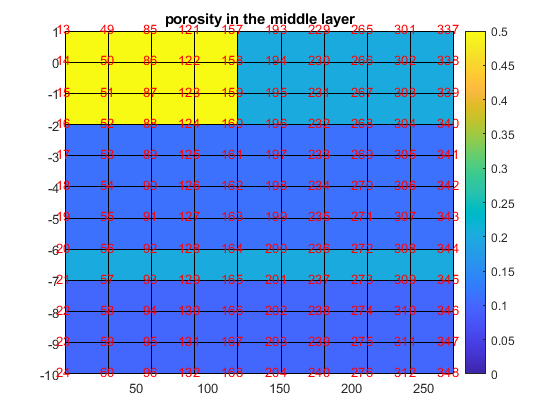

pcolor(x_nod_mtx_2d,z_nod_mtx_2d, squeeze(porosity_nod_mtx(:,2,:) ) );
colorbar;caxis([0 0.5]);
node_index_matrix_mtx              = node_index_mtx(:,2,:);
node_index_matrix_array            = node_index_matrix_mtx(:);
text(x_nod_mtx_2d(:)+0.15*dx,z_nod_mtx_2d(:)-0.2,string(node_index_matrix_array),'VerticalAlignment','bottom','HorizontalAlignment','right','color','r');
title('porosity in the middle layer');

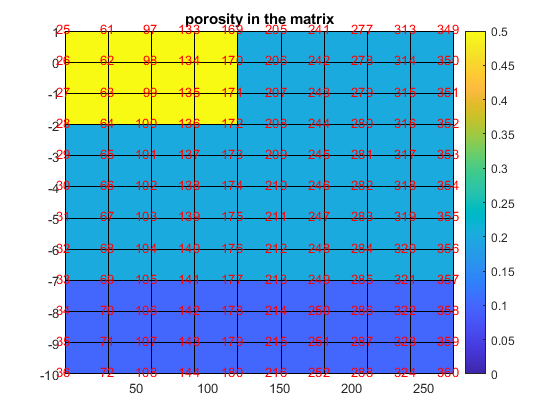

%%
pcolor(x_nod_mtx_2d,z_nod_mtx_2d, squeeze(porosity_nod_mtx(:,3,:) ) );
colorbar;caxis([0 0.5]);
node_index_matrix_mtx              = node_index_mtx(:,3,:);
node_index_matrix_array            = node_index_matrix_mtx(:);
text(x_nod_mtx_2d(:)+0.15*dx,z_nod_mtx_2d(:)-0.2,string(node_index_matrix_array),'VerticalAlignment','bottom','HorizontalAlignment','right','color','r');
title('porosity in the matrix');

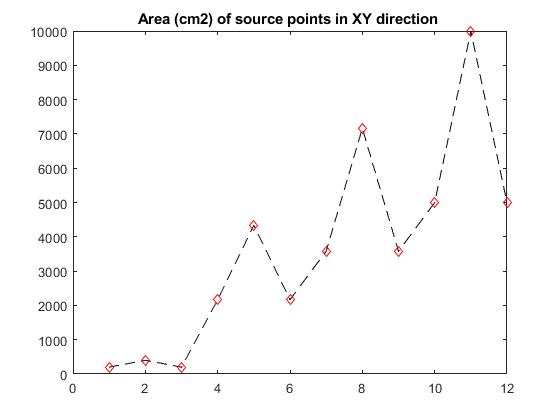

%%


pond_boundary_below_cell           = node_index_mtx(mask_nod_mtx_pond_boundary_cell)-1;
% porosity_nod_mtx_gravity_compensated(mask_porosity_nod_silt_layer_below_pond_gravity_compensatred)=porosity_silt_below_pond; % layer with low porosity

pond_boundary_cell                 = node_index_mtx(mask_nod_mtx_pond_boundary_cell);
pond_boundary_cell                 = node_index_mtx(and(z_nod_mtx_3d == min(z_nod_mtx_3d(pond_boundary_cell)),x_nod_mtx_3d <= pond_radius_m));
source_point_index                 = pond_boundary_cell;
pond_boundary_below_cell           = pond_boundary_cell+1;
evap_point_area_xy_array           = area_xy_nod_mtx_m2_3d(pond_boundary_below_cell);
source_point_area_xy_array         = area_xy_nod_mtx_m2_3d(source_point_index);
sink_point_index                   = pond_boundary_below_cell;%For evaporation. The second column is for the effective area dx*z, third column is the effective depth which is dy.
evap_point_area_xy_array           = area_xy_nod_mtx_m2_3d(pond_boundary_below_cell);
inp.iqcp                           = [source_point_index;-sink_point_index] ;
inp.qinc                           = [zeros(length(source_point_index),1); evap_point_area_xy_array ];
inp.uinc                           = [zeros(length(source_point_index),1)' 0.5*abs(dz)*ones(length(sink_point_index),1)']';%half depth of the cell
plot(source_point_area_xy_array,'--dk','MarkerEdgeColor','r');

title('Area (cm2) of source points in XY direction ');


%%
inp.nsop                           = length(inp.iqcp);
% inp.nsop                         = 0;

% porosity_nod_mtx =flip( porosity_nod_mtx);
inp.por                            = porosity_nod_mtx(:);
inp.ipbc                           = ipbc_node_idx_array;
inp.pbc                            = pbc;
inp.ubc                            = zeros(size(pbc))+c_saltwater_kgPkg;
inp.npbc                           = length(inp.pbc);
%##
%##  DATASET     22:  Ele        ment Incid      ence Data
%##    [LL]      [IIN(1)]        [IIN(2)]        [IIN(3)]        [IIN(4)]

%ne_mtx=reshape(l,ney,nex);
inp.iin1                           = zeros(inp.ne,1);
inp.iin2                           = zeros(inp.ne,1);
inp.iin3                           = zeros(inp.ne,1);
inp.iin4                           = zeros(inp.ne,1);
% DATASET 22, user need to check if the sequence of the node is in clockwise manner as suggested by the manual

%for j                             = 1:nex
%    for i                         = 1:ney
%        inp.iin1(idx)             = node_index_mtx(i,j);
%        inp.iin2(idx)             = node_index_mtx(i,j+1);
%        inp.iin3(idx)             = node_index_mtx(i+1,j+1);
%        inp.iin4(idx)             = node_index_mtx(i+1,j);
%        idx                       = idx+1;
%    end
%end


inp.iin1                           = iin1;
inp.iin2                           = iin2;
inp.iin3                           = iin3;
inp.iin4                           = iin4;
inp.iin5                           = iin5;
inp.iin6                           = iin6;
inp.iin7                           = iin7;
inp.iin8                           = iin8;
inp.export_to_file_3d();

Writting dataset 14
Elapsed time is 0.039072 seconds.
Writting dataset 15
writting dataset 17
writting dataset 19
writting dataset 22
Written to file name: PART1.inp 


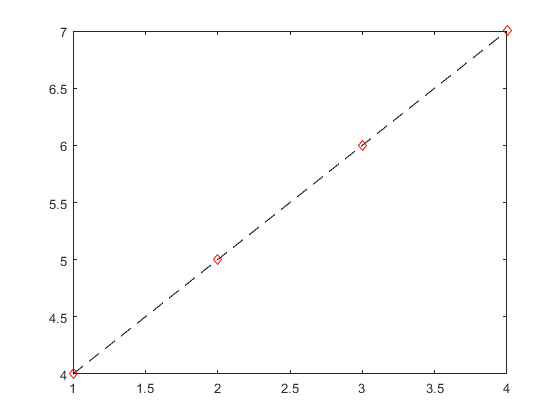


% setting the initial pressure as non hydrostatic, in particular at the sandy aquifer, the silt layer will be overwritten
pm1_mtx_pa                         = - (- depth_groundwater_table_m  + z_nod_mtx_3d) * c.g * c.rhow_pure_water;
mask_nod_mtx_silt_layer            = z_nod_mtx_3d  > depth_groundwater_table_m  ;   % mask matrix, for nod matrix 
mask_nod_mtx_sand_layer            = z_nod_mtx_3d  < depth_groundwater_table_m  ;   % mask matrix, for nod matrix 
pm1_mtx_pa(mask_nod_mtx_silt_layer)= -40000;
pm1_mtx_pa(mask_nod_mtx_sand_layer)= -(z_nod_mtx_3d(mask_nod_mtx_sand_layer) - initial_head_aquifer_m ) *c.g * (inp.rhow0 + inp.drwdu * c_saltwater_kgPkg);
ipbc_node_idx_array                = node_index_mtx(mask_nod_mtx_aquifer_boundary);
pbc                                = -(z_nod_mtx_3d(mask_nod_mtx_aquifer_boundary) - initial_head_aquifer_m ) *c.g * (inp.rhow0 + inp.drwdu * c_saltwater_kgPkg);
plot(pbc(1:size(pbc)/3)/(c.g * (inp.rhow0 + inp.drwdu * c_saltwater_kgPkg) ),'--dk','MarkerEdgeColor','r');

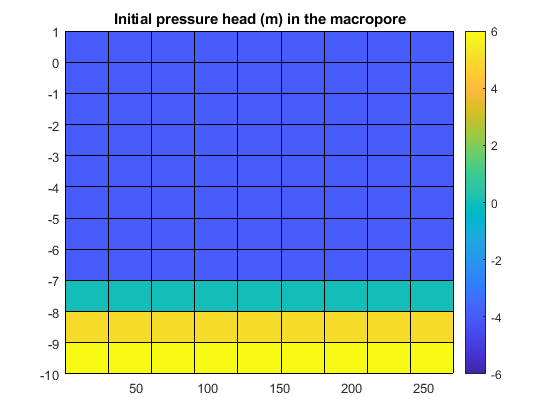

pcolor(x_nod_mtx_2d,z_nod_mtx_2d, squeeze(pm1_mtx_pa(:,1,:) )/(c.g * (inp.rhow0 + inp.drwdu * c_saltwater_kgPkg) ) );
colorbar;caxis([-6 6]);
title('Initial pressure head (m) in the macropore');


% pm1_mtx_pa=flip(pm1_mtx_pa);

% initial solute concentrtion, sandy aquifer has a saline concentration while silt has a fresh concentration
um1_mtx_kgPkg                      = zeros(size(pm1_mtx_pa)) + c_saltwater_kgPkg;
um1_mtx_kgPkg(mask_nod_mtx_silt_layer)                                                                     = c_freshwater_kgPkg;
um1_mtx_kgPkg                      = um1_mtx_kgPkg;
fprintf('use the original ics file')

use the original ics file

% ics file
ics                                = icsObj('PART1','read_from_file','no');
ics.tics                           = 0;
%ics.cpuni                         = 'UNIFORM';
%ics.pm1                           = -30;
ics.cpuni                          = 'NONUNIFORM';
ics.pm1                            = pm1_mtx_pa(:);
ics.cuuni                          = 'NONUNIFORM';
ics.um1                            = um1_mtx_kgPkg ;
ics.export_to_file();

Writting to file PART1.ics



bcs=bcsObj('read_from_file','no');
bcs.uname='PART1.bcs';
bcs.terms.bcssch='Timed_Obs';

bcs.terms.data(1).bcsid            = 'ts800';
bcs.terms.data(1).nsop1            = length(source_point_index);
bcs.terms.data(1).nsou1            = 0;
bcs.terms.data(1).npbc1            = 0;
bcs.terms.data(1).nubc1            = 0;
bcs.terms.data(1).iqcp1            = source_point_index;   %note that if there is more than one node, they have to be specified in an column
bcs.terms.data(1).qinc1            = [0.95 * 69.45 * (source_point_area_xy_array)/sum(source_point_area_xy_array)];
bcs.terms.data(1).uinc1            = [1e-4 * ones(length(source_point_index),1)];


bcs.terms.data(2).bcsid            = 'ts801';
bcs.terms.data(2).nsop1            = length(source_point_index);
bcs.terms.data(2).nsou1            = 0;
bcs.terms.data(2).npbc1            = 0;
bcs.terms.data(2).nubc1            = 0;
bcs.terms.data(2).iqcp1            = source_point_index;   %note that if there is more than one node, they have to be specified in an column
bcs.terms.data(2).qinc1            = [zeros(length(source_point_index),1)];
bcs.terms.data(2).uinc1            = [zeros(length(source_point_index),1)];

bcs.terms.data(3).bcsid            = 'ts802';
bcs.terms.data(3).nsop1            = length(source_point_index);
bcs.terms.data(3).nsou1            = 0;
bcs.terms.data(3).npbc1            = 0;
bcs.terms.data(3).nubc1            = 0;
bcs.terms.data(3).iqcp1            = source_point_index;   %note that if there is more than one node, they have to be specified in an column
bcs.terms.data(3).qinc1            = [1.2*69.45*(source_point_area_xy_array)/sum(source_point_area_xy_array)];
bcs.terms.data(3).uinc1            = [1e-4*ones(length(source_point_index),1)];

bcs.terms.data(4).bcsid            = 'ts803';
bcs.terms.data(4).nsop1            = length(source_point_index);
bcs.terms.data(4).nsou1            = 0;
bcs.terms.data(4).npbc1            = 0;
bcs.terms.data(4).nubc1            = 0;
bcs.terms.data(4).iqcp1            = source_point_index;   %note that if there is more than one node, they have to be specified in an column
bcs.terms.data(4).qinc1            = [zeros(length(source_point_index),1)];
bcs.terms.data(4).uinc1            = [zeros(length(source_point_index),1)];

bcs.terms.data(5).bcsid            = 'ts804';
bcs.terms.data(5).nsop1            = length(source_point_index);
bcs.terms.data(5).nsou1            = 0;
bcs.terms.data(5).npbc1            = 0;
bcs.terms.data(5).nubc1            = 0;
bcs.terms.data(5).iqcp1            = source_point_index;   %note that if there is more than one node, they have to be specified in an column
bcs.terms.data(5).qinc1            = [0.3*(source_point_area_xy_array)/sum(source_point_area_xy_array)];;
bcs.terms.data(5).uinc1            = [1e-4*ones(length(source_point_index),1)];

bcs.terms.data(6).bcsid            = 'ts805';
bcs.terms.data(6).nsop1            = length(source_point_index);
bcs.terms.data(6).nsou1            = 0;
bcs.terms.data(6).npbc1            = 0;
bcs.terms.data(6).nubc1            = 0;
bcs.terms.data(6).iqcp1            = source_point_index;   %note that if there is more than one node, they have to be specified in an column
bcs.terms.data(6).qinc1            = [zeros(length(source_point_index),1)];
bcs.terms.data(6).uinc1            = [zeros(length(source_point_index),1)];

bcs.terms.data(7).bcsid            = 'ts806';
bcs.terms.data(7).nsop1            = length(source_point_index);
bcs.terms.data(7).nsou1            = 0;
bcs.terms.data(7).npbc1            = 0;
bcs.terms.data(7).nubc1            = 0;
bcs.terms.data(7).iqcp1            = source_point_index;   %note that if there is more than one node, they have to be specified in an column
bcs.terms.data(7).qinc1            = [0.83*69.45*(source_point_area_xy_array)/sum(source_point_area_xy_array)];
bcs.terms.data(7).uinc1            = [1e-4*ones(length(source_point_index),1)];

bcs.terms.data(8).bcsid            = 'ts807';
bcs.terms.data(8).nsop1            = length(source_point_index);
bcs.terms.data(8).nsou1            = 0;
bcs.terms.data(8).npbc1            = 0;
bcs.terms.data(8).nubc1            = 0;
bcs.terms.data(8).iqcp1            = source_point_index;   %note that if there is more than one node, they have to be specified in an column
bcs.terms.data(8).qinc1            = [zeros(length(source_point_index),1)];
bcs.terms.data(8).uinc1            = [zeros(length(source_point_index),1)];
bcs.export_to_file();

Writting to file PART1.bcs
There are  8 time steps to be specificed in the bcs file 'PART1.bcs'


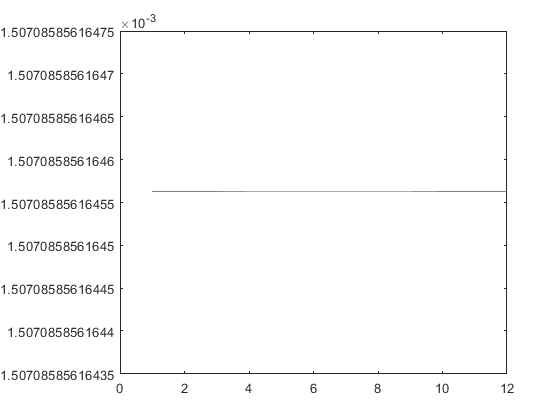

plot((bcs.terms.data(1).qinc1) ./ source_point_area_xy_array);